# Parameterization of eCLARI Locomotion Surfaces

## Define the Symbolic Structure

This will be used later to plot configurations of interest.

syms t ankk bNE bNW bSW bSE
syms g a l 

r_E = 2*l*[sin(g); 
            0;
            0];
r_N = 2*l*[0; 
            cos(g);
            0];
r_W = -2*l*[sin(g); 
            0;
            0];
r_S = -2*l*[0; 
            cos(g);
            0];

b_NE = (r_N + r_E)/2;
b_NW = (r_N + r_W)/2;
b_SW = (r_S + r_W)/2;
b_SE = (r_S + r_E)/2;

L_NE = a*l*[cos(bNE + g); 
            sin(bNE + g);
            0];

L_NW = a*l*[-cos(bNW - g); 
            -sin(bNW - g);
            0];

L_SW = a*l*[-cos(bSW + g); 
            -sin(bSW + g);
            0];
        
L_SE = a*l*[cos(bSE - g); 
            sin(bSE - g); 
            0];

l_NE = r_N - r_E;
l_NW = r_W - r_N;
l_SW = r_S - r_W;
l_SE = r_E - r_S;

leg_NE = b_NE + L_NE;
leg_NW = b_NW + L_NW;
leg_SW = b_SW + L_SW;
leg_SE = b_SE + L_SE;

Kvec = leg_NE - leg_NW;

syms th

YawCL = [cos(th), -sin(th), 0;
        sin(th), cos(th), 0;
        0, 0, 1];

sim = [];

sim.leg_NE = leg_NE;
sim.leg_NW = leg_NW;
sim.leg_SW = leg_SW;
sim.leg_SE = leg_SE;
sim.YawCL = YawCL;
sim.Kvec = Kvec;
sim.b_NE = b_NE; sim.b_NW = b_NW;
sim.b_SE = b_SE; sim.b_SW = b_SW;
sim.r_E = r_E; sim.r_N = r_N; 
sim.r_W = r_W; sim.r_S = r_S;

## Extracting the boundary

Let's import the solution data for eCLARI when A = 1 which corresponds to our current robot leg design.

% Initialize parameters we need
nD = 15;
g0 = pi/4;
b10 = 0; b20 = b10;
ank = pi/4;
b_FR = linspace(-ank,ank,nD); b_FL = linspace(-ank,ank,nD);
[B1,B2] = meshgrid(b_FR,b_FL);
L = 1.2;
bl = 4*L*cos(pi/4);
A = [0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0, 1.1, 1.2, 1.3, 1.4, 1.5]; 

% LOAD THE DATA:
load(['Locomotion Surface Sweeps\W3 November 2021\A varied\LocoSURF_Avar_November2021_L-1pt2cm_a1pt0_ank45_',...
'gamma0_betaAMP_grid_size_', num2str(nD), 'x',...
num2str(nD), 'x', num2str(numel(A)), '.mat'],'G','Th','R','numS');

% Some additional data conditioning:
limL = 0; limH = pi/2;
[inpC, G, Th, R] = ...
    CLARISpaceClassifier2full(G,Th,R,A,B1,B2,b10,b20,g0,limL,limH,numS);
[G, ~, ~] = classifyClariSURF(inpC, G, Th, R, numS);

% Get the sweep index at A = 1.
n = 10;
% Small debugg for the new classifier:
G2 = reshape(G(n,:,:,2),size(G,2),size(G,3)); % Just get the first set of solutions. 
% Th = reshape(Th(n,:,:,:),size(Th,2),size(Th,3),size(Th,4)); 
% R = reshape(R(:,:,n,:,:),size(R,1),size(R,2),size(R,4),size(R,5)); 
A = A(n); 
numS = reshape(numS(n,:,:),size(numS,2),size(numS,3));

Now, we can plot the $\gamma
$ surface to get an idea as to what the boundary looks like,

figure()
surf(B1,B2,rad2deg(2*G2),'EdgeColor','none','FaceAlpha',0.5); hold on;
view(0,90); colormap(jet); xlabel('\beta_{FR}'); ylabel('\beta_{FL}');
title(['Boundaries of \gamma at a = ',num2str(A)]);

Let's add a boundary to this,

% Let's isolate the indices we care about first (FR and FL legs):
b_FR = B1(numS > 0); b_FL = B2(numS > 0); % g2 = G2(numS > 0);

% by logically indexing numS, we obtain only the points where a solution exists
bV = boundary(b_FR,b_FL);

% Now, we use the logical indices to plot the boundary
plot(b_FR(bV),b_FL(bV),'k--','linewidth',1,'DisplayName','non-compact boundary');

Some points are missed, so let's try that again by setting the shrink factor to 1,

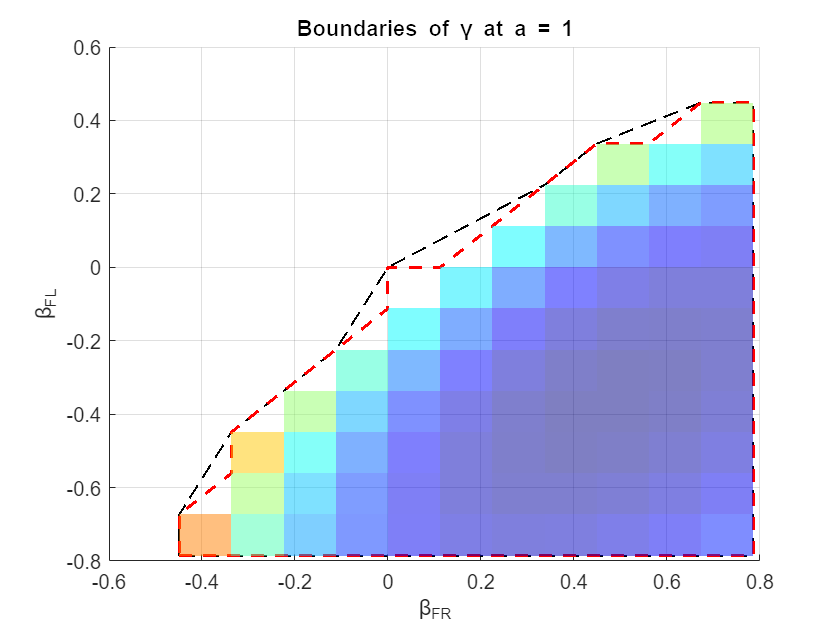

bV = boundary(b_FR,b_FL,1); plot(b_FR(bV),b_FL(bV),'r--','linewidth',1.5,'DisplayName','compact boundary');

*The gap in the middle inside the compact boundary comes from a bifurcation solution that is neither a part of the first solution branch nor the second.*

## Parameterizing the boundary using polynomials

Now, we can proceed and plot each axis as separate functions of say $\mathbf{\phi_b}$ (*boundary phase*),

% We remove the last point because, we describe the variation in each axis
% as a periodic function.
phi_b = linspace(0,1,length(bV)+1); phi_b = phi_b(1:end-1);

% Plotting the boundary coordinates separately,
figure()
plot(phi_b,b_FR(bV),'ro','LineWidth',1.5,'DisplayName','\beta_{FR}');
hold on; grid on;
plot(phi_b,b_FL(bV),'ko','LineWidth',1.5,'DisplayName','\beta_{FL}');
% set(get(get(p1, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off'); % legend off
xlabel('Boundary Phase \phi_b');
ylabel('Boundary Coordinate');
title('Phase-based boundary representation'); legend('location','northeast');

Let's start fitting polynomial models to this,

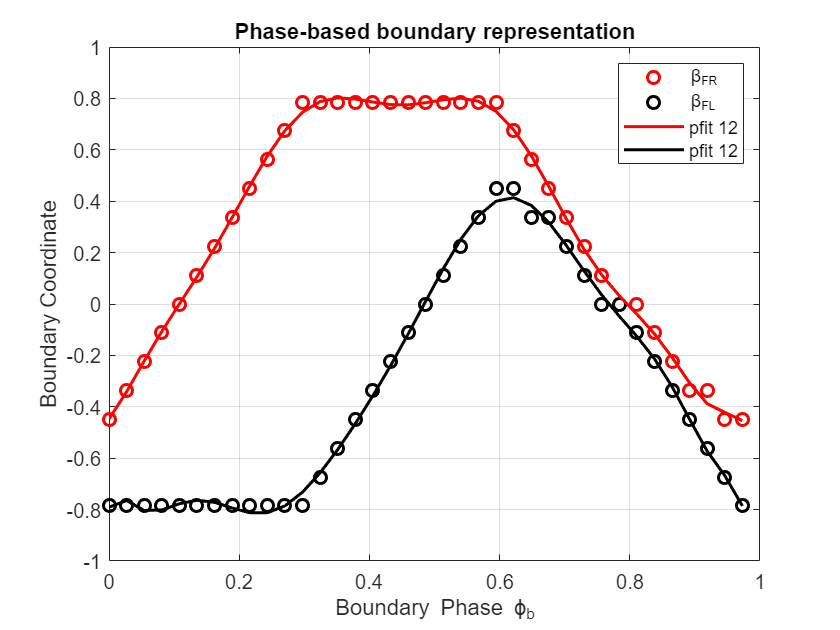

% order of the polynomial fit:
nFit = 12;
% Lets fit polynomials to the front-right and left-leg motions:
p_FR = polyfit(phi_b,b_FR(bV),nFit); p_FL = polyfit(phi_b,b_FL(bV),nFit);

% Plot these fits with correspondingly colored lines
plot(phi_b,polyval(p_FR,phi_b),'r','LineWidth',1.5,'DisplayName',['pfit ',num2str(nFit)]);
plot(phi_b,polyval(p_FL,phi_b),'k','LineWidth',1.5,'DisplayName',['pfit ',num2str(nFit)]);

Let's plot this as a boundary around the countour plot just to see how this looks.

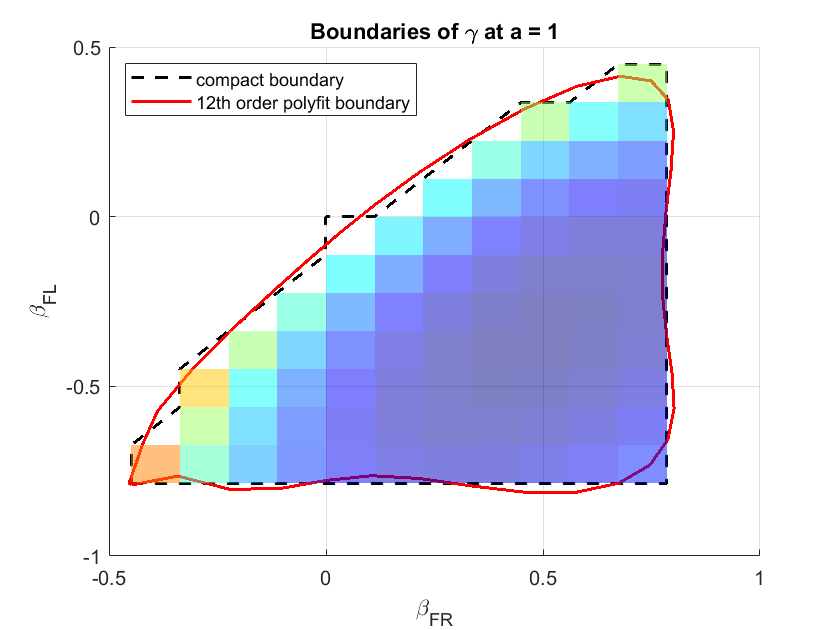

figure()
p1 = surf(B1,B2,rad2deg(2*G2),'EdgeColor','none','FaceAlpha',0.5);
set(get(get(p1, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
hold on;
view(0,90); colormap(jet);
plot(b_FR(bV),b_FL(bV),'k--','linewidth',1.5,'DisplayName','compact boundary');
plot(polyval(p_FR,[phi_b phi_b(1)]),polyval(p_FL,[phi_b phi_b(1)]),'r',...
    'LineWidth',1.5,'DisplayName',[num2str(nFit),'th order polyfit boundary']);
xlabel('\beta_{FR}'); ylabel('\beta_{FL}');
title('Boundaries of \gamma at a = 1'); legend('location','northwest');

## Extending the fit to other sweep points

Here, we shall extend the fit to other values of leg-link fraction '*a' *values in a loop. First, we shall make and plot fits at each swept value.

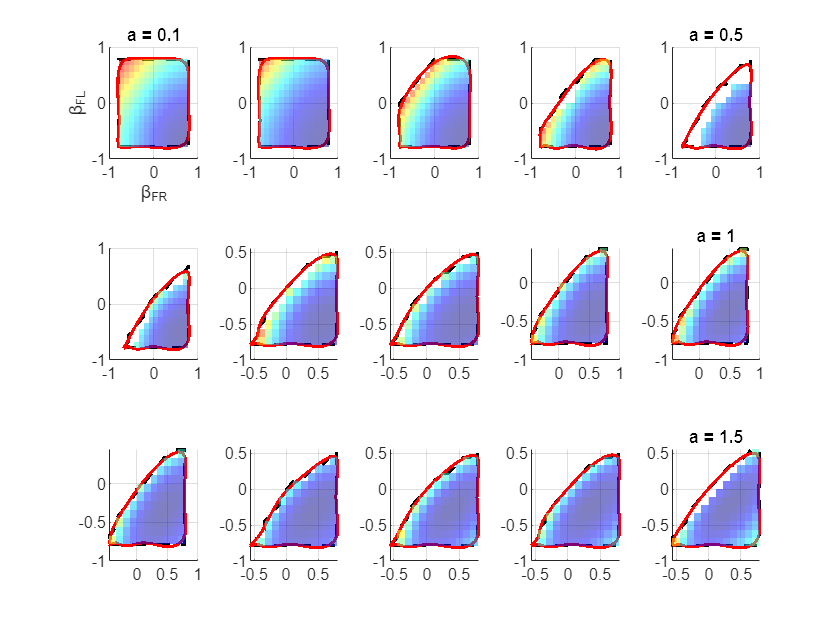

% Reload the data
A = [0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0, 1.1, 1.2, 1.3, 1.4, 1.5];
load(['Locomotion Surface Sweeps\W3 November 2021\A varied\LocoSURF_Avar_November2021_L-1pt2cm_a1pt0_ank45_',...
'gamma0_betaAMP_grid_size_', num2str(nD), 'x',...
num2str(nD), 'x', num2str(numel(A)), '.mat'],'G','K','Th','R','T','numS');
limL = 0; limH = pi/2;
[inpC, G, Th, R] = ...
    CLARISpaceClassifier2full(G,Th,R,A,B1,B2,b10,b20,g0,limL,limH,numS);
[G, Th, R] = classifyClariSURF(inpC, G, Th, R, numS);

% Set the polynomial order for the fit
nFit = 12;

% Create a vector that will store the polynomial fits each boundary
% direction.
P_FR = nan(length(A),nFit+1); P_FL = nan(length(A),nFit+1);

% Start the tiled layout:
tiledlayout(3,length(A)/3);

% Loop over A:
for i = 1:length(A)
    
    % Extract the first gamma solution, corresponding a value, and number
    % of solutions array.
    A_temp = A(i); 
    G_temp = reshape(G(i,:,:,2),size(G,2),size(G,3)); 
    numS_temp = reshape(numS(i,:,:),size(numS,2),size(numS,3));
    
    % Now, get the boundary and start fitting stuff to it.
    b_FR = B1(numS_temp > 0); b_FL = B2(numS_temp > 0);
    bV = boundary(b_FR,b_FL,1);
    phi_b = linspace(0,1,length(bV)+1); phi_b = phi_b(1:end-1);
    
    % Store the fit in the ith row of the main array:
    P_FR(i,:) = polyfit(phi_b,b_FR(bV),nFit); P_FL(i,:) = polyfit(phi_b,b_FL(bV),nFit);
    
    % Plot the results in the corresponding tile:
    nexttile
    surf(B1,B2,rad2deg(2*G_temp),'EdgeColor','none','FaceAlpha',0.5);
    hold on;
    view(0,90); colormap(jet);
    plot(b_FR(bV),b_FL(bV),'k--','linewidth',1.5);
    plot(polyval(P_FR(i,:),[phi_b phi_b(1)]),polyval(P_FL(i,:),[phi_b phi_b(1)]),'r',...
    'LineWidth',1.5);
    if i == 1
        xlabel('\beta_{FR}'); ylabel('\beta_{FL}');
        title(['a = ',num2str(A_temp)]);
    elseif mod(i,5) == 0
        title(['a = ',num2str(A_temp)]);
    end
end

Sometimes, you see empty spaces, but the there is a lack of solution because the solutions belong to the second branch and is hence not highlighted by the first one. 

Since we have used the same order polynomial, **we can look at how each coefficient changes as a value changes.** **This makes each coefficient then a polynomial in 'a' or the sweep variable.**

% Decide the fit order:
nFit2 = 11;

% Initialize storage containers:
P_FR_full = nan(nFit2+1,nFit+1); P_FL_full = P_FR_full;

% Start the tiled layout
tiledlayout(5,ceil(size(P_FR,2)/5));

% fitting coefficients with a:
for i = 1:size(P_FR,2)
    
    % Fit
    P_FR_full(:,i) = polyfit(A,P_FR(:,i),nFit2);
    P_FL_full(:,i) = polyfit(A,P_FL(:,i),nFit2);
    
    % Make the plot for the 
    nexttile
    plot(A,P_FR(:,i),'ro','LineWidth',1.5);
    hold on; grid on;
    plot(A,P_FL(:,i),'kx','LineWidth',1.5);
    plot(A,polyval(P_FR_full(:,i),A),'r','LineWidth',1.2);
    plot(A,polyval(P_FL_full(:,i),A),'k','LineWidth',1.2);
    title(['coeff ',num2str(i)]);
    
end
sgtitle(['order - ',num2str(nFit2)]);

Let's finally test this fit by plotting the complete fit for a select 3 values of A around the range of (0.8 to 1.2).

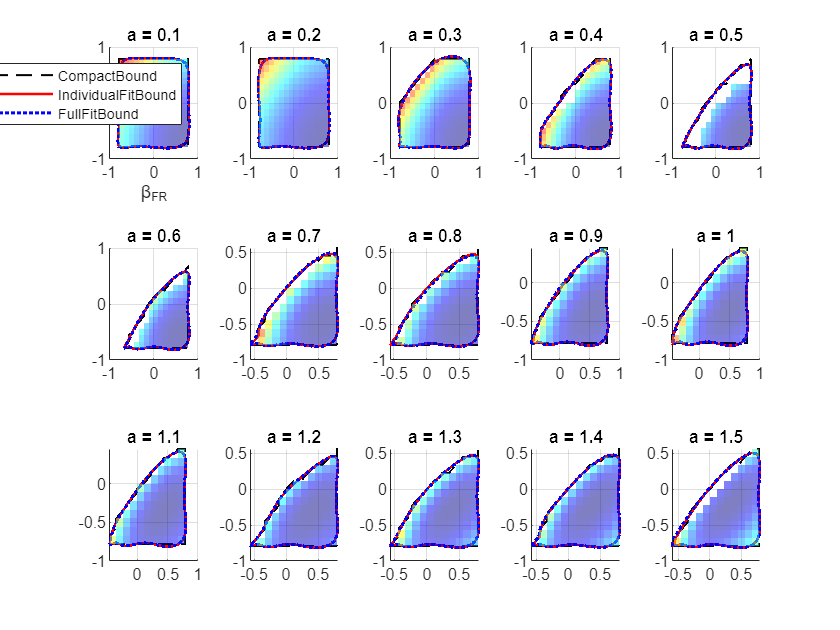

tiledlayout(3,length(A)/3);

for i = 1:length(A)
    
    A_temp = A(i); 
    G_temp = reshape(G(i,:,:,2),size(G,2),size(G,3)); 
    numS_temp = reshape(numS(i,:,:),size(numS,2),size(numS,3));
    
    b_FR = B1(numS_temp > 0); b_FL = B2(numS_temp > 0);
    bV = boundary(b_FR,b_FL,1);
    phi_b = linspace(0,1,length(bV)+1); phi_b = phi_b(1:end-1);
    
    % Get the evaluation vector
    phi_bE = [phi_b phi_b(1)];
    
    % Create a A vector to get the polyval out:
    AVec = nan(1,nFit2+1);
    for j = 1:nFit2+1
        AVec(j) = A_temp^(j-1);
    end
    AVec = fliplr(AVec);
    % Now, we are ready to get the evaluate the boundary!
    
    nexttile
    p1 = surf(B1,B2,rad2deg(2*G_temp),'EdgeColor','none','FaceAlpha',0.5);
    set(get(get(p1, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    hold on;
    view(0,90); colormap(jet);
    plot(b_FR(bV),b_FL(bV),'k--','linewidth',1.0,'DisplayName','CompactBound');
    plot(polyval(P_FR(i,:),phi_bE),polyval(P_FL(i,:),phi_bE),'r',...
    'LineWidth',1.2,'DisplayName','IndividualFitBound');
    plot(polyval(AVec*P_FR_full,phi_bE),polyval(AVec*P_FL_full,phi_bE),'b:',...
    'LineWidth',1.5,'DisplayName','FullFitBound');
    if i == 1
        xlabel('\beta_{FR}'); ylabel('\beta_{FL}');
        legend('location','northeast');
    end
    title(['a = ',num2str(A_temp)]);
    
end

This works great! But, ***could we also get the same result through the bifrucation expression that we obtained from inverting ***$\omega_1$***?***

## Bifurcations solutions

We start by looking at the determinant of $\omega_1$ values computed earlier in the classifier function and this will help us pull out the bifurcation regions since they will not be exactly zero, and hence we need to do some numerical thresholding. Let's sort the absolute value of this array,

% First only display the points where a single solution exists:
DetOmega_1 = inpC.DetOmega_1(numS == 1);
% this will automatically flatten our result from the higher dimension
DetOmega_1 = sort(abs(DetOmega_1(~isnan(DetOmega_1))))

DetOmega_1 =     0.0000
    0.0203
    0.0203
    0.0419
    0.0447
    0.0447
    0.0533
    0.0533
    0.0672
    0.0672


Now, we can look at the histogram of this data,

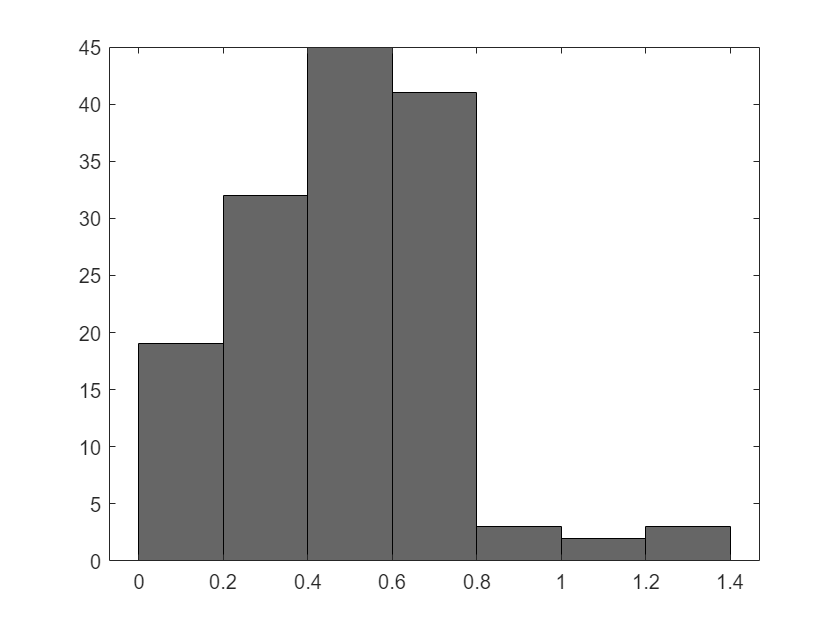

figure()
histogram(DetOmega_1, 'FaceColor','k')

Seems like we do have some values very close to 0. Let's sort and look at these values through a normal plot,

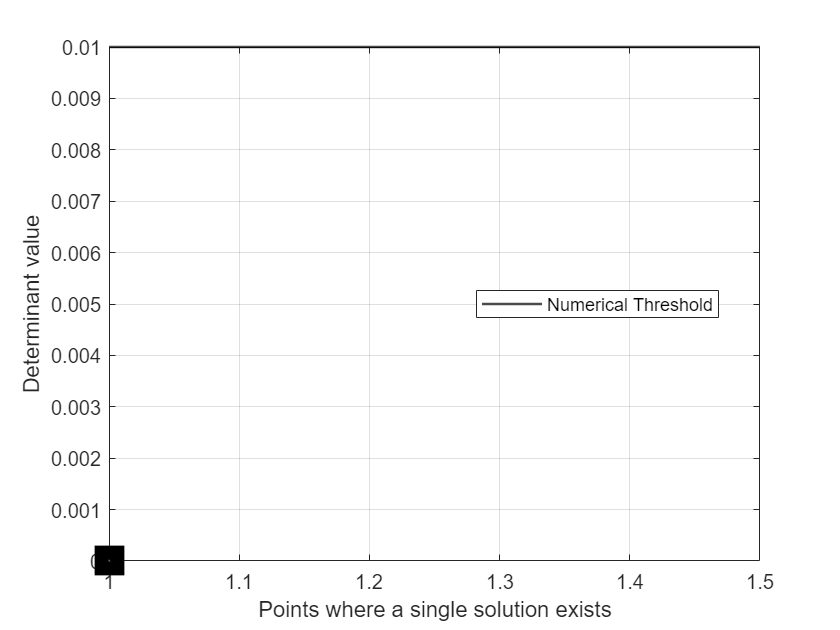

figure()
p1 = plot(DetOmega_1, 'ks', 'MarkerSize', 10, 'LineWidth',10); hold on; grid on;
set(get(get(p1, 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
ylim([0 1e-2]); yline(1e-2,'k', 'linewidth',1.2, 'DisplayName', 'Numerical Threshold'); % manually set limit
xlabel('Points where a single solution exists'); ylabel('Determinant value');
legend('location','best');

Here, we arbitrarily set the limits to 1e-10 (this is chosen because all evaluations below this threshold are the closest to 0), and we have like 2 points at the bifurcation (numerically close with a ball around the zero set at 1e-3). Let's display these points now (column order of the list: ***A b10 b20 g0 B1 B2 G Th R(1x3) DetOmega_1***)

BifList = inpC.BifList;
BifList

BifList =     1.0000         0         0    0.7854         0         0    0.7854         0         0         0         0    0.0000
    1.5000         0         0    0.7854         0         0    0.7854         0         0         0         0    1.2500


Let's print these configurations below,

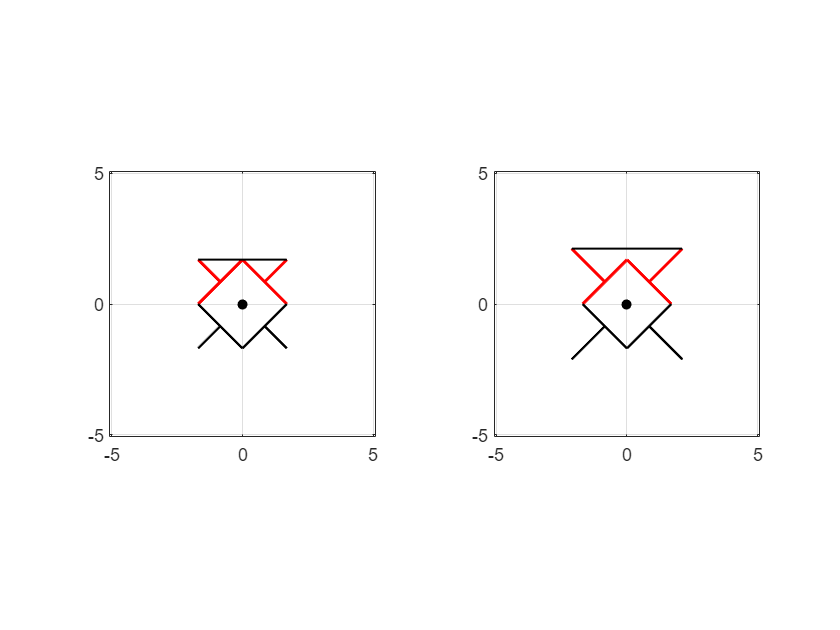

figure()
tiledlayout(1,size(BifList,1))
for i = 1:size(BifList,1)
    p = nexttile(i);
    % Plot the other state
    printCLARIconfig(p,ank,[1,0,0],L,BifList(i,1),BifList(i,7),BifList(i,8),BifList(i,9:11)',BifList(i,5),BifList(i,6),sim,bl,2)
end

In the next section, we shall see how to these points behave when considering the mathematical solution.

## Bifurcation-based boundary representation (why/how it doesn't work)

We briefly tried to obtain a generalized solution in the Geometric Mechanics livescript, but the we just used the expression as a bifurcation classifier. Here, we shall try to obtain conditions on the boundary that we are trying to classify in our problems.

syms b1 b2 g a real
assume(b1 <= pi/4 & b1 >= -pi/4);
assume(b2 <= pi/4 & b2 >= -pi/4);
assume(g <= pi/2 & g >= 0);
expr01_det_sym = (a^2)*sin(b1 - b2 +2*g) - sin(2*g) - a*cos(b2 - 2*g) - a*cos(b1 + 2*g)

$$expr01\_det\_sym = a^{2}\,\sin\left(b_{1}-b_{2}+2\,g\right)-a\,\cos\left(b_{1}+2\,g\right)-a\,\cos\left(b_{2}-2\,g\right)-\sin\left(2\,g\right)$$

Here, b1 and b2 are the FR and FL leg angles and g is half the body angle.

bifSol = solve(expr01_det_sym == 0, [b1 b2], 'Real', true, 'ReturnConditions', true)

bifSol = struct with fields:
            b1: [2×1 sym]
            b2: [2×1 sym]
    parameters: [k    x]
    conditions: [2×1 sym]


Let's display each object in our 'bifSol' container,

bifSol.b1 = simplify(bifSol.b1, 'Steps', 50); bifSol.b2 = simplify(bifSol.b2, 'Steps', 50);
bifSol.conditions = simplify(bifSol.conditions, 'Steps', 50);
bifSol.b1

$$ans = \begin{array}{l} \left(\begin{array}{c} 2\,\pi \,k-2\,\mathrm{atan}\left(\frac{\sigma_{1}-a^{2}\,\left(2\,{\sin\left(\frac{x}{2}\right)}^{2}-1\right)}{\sigma_{2}}\right)-2\,g\\ 2\,\mathrm{atan}\left(\frac{\sigma_{1}+a^{2}\,\left(2\,{\sin\left(\frac{x}{2}\right)}^{2}-1\right)}{\sigma_{2}}\right)-2\,g+2\,\pi \,k \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2\,a^{3}\,\sin\left(x\right)-a\,\sin\left(4\,g-x\right)-{\sin\left(2\,g\right)}^{2}-a\,\sin\left(x\right)+\frac{a^{2}\,\left(2\,{\sin\left(2\,g-x\right)}^{2}-1\right)}{2}+\frac{a^{2}}{2}+a^{4}}\\ \sigma_{2}=\sin\left(x\right)\,a^{2}+2\,a\,{\sin\left(g-\frac{x}{2}\right)}^{2}-\sin\left(2\,g\right) \end{array}$$

bifSol.b2

$$ans = \left(\begin{array}{c} x\\ x \end{array}\right)$$

bifSol.parameters % leave this as is

$$ans = \left(\begin{array}{cc} k & x \end{array}\right)$$

bifSol.conditions

$$ans = \begin{array}{l} \left(\begin{array}{c} 2\,\pi \,k-\sigma_{5}\leq \sigma_{2}\wedge \sigma_{3}\leq \sigma_{1}\wedge k\in \mathbb{Z}\wedge x\leq \frac{\pi }{4}\wedge -\frac{\pi }{4}\leq x\wedge 2\,g\leq \frac{\pi }{4}-\sigma_{5}+2\,\pi \,k\\ \sigma_{4}+2\,\pi \,k\leq \sigma_{2}\wedge \sigma_{3}\leq \sigma_{1}\wedge k\in \mathbb{Z}\wedge x\leq \frac{\pi }{4}\wedge -\frac{\pi }{4}\leq x\wedge 2\,g\leq \frac{\pi }{4}+\sigma_{4}+2\,\pi \,k \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a^{4}+2\,\sin\left(x\right)\,a^{3}+4\,a^{2}\,{\cos\left(g\right)}^{2}\,{\cos\left(x\right)}^{2}+4\,\sin\left(g\right)\,\sin\left(x\right)\,a^{2}\,\cos\left(g\right)\,\cos\left(x\right)+a^{2}+4\,\sin\left(g\right)\,a\,\cos\left(g\right)\,\cos\left(x\right)+4\,{\cos\left(g\right)}^{4}\\ \sigma_{2}=2\,g+\frac{\pi }{4}\\ \sigma_{3}=a\,\left(a\,{\cos\left(x\right)}^{2}-8\,{\sin\left(g\right)}^{2}\,\sin\left(x\right)\,\sigma_{6}+4\,a\,{\cos\left(g\right)}^{4}\,{\cos\left(x\right)}^{2}+8\,{\cos\left(g\right)}^{3}\,\sin\left(g\right)\,\cos\left(x\right)-4\,a\,{\sin\left(g\right)}^{2}\,{\sin\left(x\right)}^{2}\,\sigma_{6}+8\,a\,{\cos\left(g\right)}^{3}\,\sin\left(g\right)\,\cos\left(x\right)\,\sin\left(x\right)\right)+4\,{\cos\left(g\right)}^{2}\\ \sigma_{4}=2\,\mathrm{atan}\left(\frac{\sigma_{7}-\sigma_{9}}{\sigma_{8}}\right)\\ \sigma_{5}=2\,\mathrm{atan}\left(\frac{\sigma_{7}+\sigma_{9}}{\sigma_{8}}\right)\\ \sigma_{6}={\sin\left(g\right)}^{2}-1\\ \sigma_{7}=\sqrt{2}\,\sqrt{\cos\left(4\,g\right)+4\,a^{3}\,\sin\left(x\right)-2\,a\,\sin\left(4\,g-x\right)-a^{2}\,\cos\left(4\,g-2\,x\right)-2\,a\,\sin\left(x\right)+a^{2}+2\,a^{4}-1}\\ \sigma_{8}=2\,\left(a-\sin\left(2\,g\right)+a^{2}\,\sin\left(x\right)-a\,\cos\left(2\,g-x\right)\right)\\ \sigma_{9}=2\,a^{2}\,\cos\left(x\right) \end{array}$$

Alright, this seems to provide us with two classes of solutions. Since we can't have robot links intersecting each other, we shall substitute the parameter 'k' to be 0. This way, we will look at exactly the formulation we need for the boundary representation.

%%% Here, we shall make changes and update the solution structure.
% Substitute for the solutions:
b1_sol_1 = simplify(subs(bifSol.b1(1), bifSol.parameters(1), 0), 'steps', 50);
b1_sol_2 = simplify(subs(bifSol.b1(2), bifSol.parameters(1), 0), 'steps', 50);
b2_sol_1 = simplify(subs(bifSol.b2(1), bifSol.parameters(1), 0), 'steps', 50);
b2_sol_2 = simplify(subs(bifSol.b2(2), bifSol.parameters(1), 0), 'steps', 50);
bifSol.b1 = [b1_sol_1; b1_sol_2];
bifSol.b2 = [b2_sol_1; b2_sol_2];
% Now, we substitute for the conditions:
cond_1 = simplify(subs(bifSol.conditions(1), bifSol.parameters(1), 0), 'Steps', 50);
cond_2 = simplify(subs(bifSol.conditions(1), bifSol.parameters(1), 0), 'Steps', 50);
bifSol.conditions = [cond_1; cond_2];
% Remove k from the parameters to reflect the changes we made
bifSol.parameters = bifSol.parameters(2);

% Now, we display the result:
bifSol.b1

$$ans = \begin{array}{l} \left(\begin{array}{c} -2\,g-2\,\mathrm{atan}\left(\frac{\sigma_{1}+a^{2}\,\cos\left(x\right)}{\sigma_{2}}\right)\\ 2\,\mathrm{atan}\left(\frac{\sigma_{1}-a^{2}\,\cos\left(x\right)}{\sigma_{2}}\right)-2\,g \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2\,a^{3}\,\sin\left(x\right)-a\,\sin\left(4\,g-x\right)-{\sin\left(2\,g\right)}^{2}-a\,\sin\left(x\right)+a^{4}+a^{2}\,{\sin\left(2\,g-x\right)}^{2}}\\ \sigma_{2}=\sin\left(x\right)\,a^{2}+2\,a\,{\sin\left(g-\frac{x}{2}\right)}^{2}-\sin\left(2\,g\right) \end{array}$$

bifSol.b2

$$ans = \left(\begin{array}{c} x\\ x \end{array}\right)$$

bifSol.parameters

$$ans = x$$

bifSol.conditions

$$ans = \begin{array}{l} \left(\begin{array}{c} \sigma_{4}\leq \sigma_{2}\wedge \sigma_{1}\leq \sigma_{3}\wedge 2\,g\leq \frac{\pi }{4}+\sigma_{1}\wedge x\leq \frac{\pi }{4}\wedge -\frac{\pi }{4}\leq x\\ \sigma_{4}\leq \sigma_{2}\wedge \sigma_{1}\leq \sigma_{3}\wedge 2\,g\leq \frac{\pi }{4}+\sigma_{1}\wedge x\leq \frac{\pi }{4}\wedge -\frac{\pi }{4}\leq x \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-2\,\mathrm{atan}\left(\frac{\sqrt{2}\,\sqrt{\cos\left(4\,g\right)+4\,a^{3}\,\sin\left(x\right)-2\,a\,\sin\left(4\,g-x\right)-a^{2}\,\cos\left(4\,g-2\,x\right)-2\,a\,\sin\left(x\right)+a^{2}+2\,a^{4}-1}+2\,a^{2}\,\cos\left(x\right)}{2\,\left(a-\sin\left(2\,g\right)+a^{2}\,\sin\left(x\right)-a\,\cos\left(2\,g-x\right)\right)}\right)\\ \sigma_{2}=a^{4}+2\,\sin\left(x\right)\,a^{3}+4\,a^{2}\,{\cos\left(g\right)}^{2}\,{\cos\left(x\right)}^{2}+4\,\sin\left(g\right)\,\sin\left(x\right)\,a^{2}\,\cos\left(g\right)\,\cos\left(x\right)+a^{2}+4\,\sin\left(g\right)\,a\,\cos\left(g\right)\,\cos\left(x\right)+4\,{\cos\left(g\right)}^{4}\\ \sigma_{3}=2\,g+\frac{\pi }{4}\\ \sigma_{4}=a\,\left(a\,{\cos\left(x\right)}^{2}-8\,{\sin\left(g\right)}^{2}\,\sin\left(x\right)\,\sigma_{5}+4\,a\,{\cos\left(g\right)}^{4}\,{\cos\left(x\right)}^{2}+8\,{\cos\left(g\right)}^{3}\,\sin\left(g\right)\,\cos\left(x\right)-4\,a\,{\sin\left(g\right)}^{2}\,{\sin\left(x\right)}^{2}\,\sigma_{5}+8\,a\,{\cos\left(g\right)}^{3}\,\sin\left(g\right)\,\cos\left(x\right)\,\sin\left(x\right)\right)+4\,{\cos\left(g\right)}^{2}\\ \sigma_{5}={\sin\left(g\right)}^{2}-1 \end{array}$$

Let's try to investigate this by subbing in known solutions listed in `BifList` array.

- **Robot Equilibrium Case (both entries in the list)**

We shall do this step by step to see what happens to two both solutions simultaneously,

subs(bifSol.b2, bifSol.parameters, BifList(1,6))

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Zero as expected since we are directly substituting **x = 0.**

subs(bifSol.b1, bifSol.parameters, BifList(1,6)) % , a, g | , BifList(1,1), BifList(1,7)

$$ans = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\sigma_{1}+a^{2}}{\sin\left(2\,g\right)-2\,a\,{\sin\left(g\right)}^{2}}\right)-2\,g\\ -2\,g-2\,\mathrm{atan}\left(\frac{\sigma_{1}-a^{2}}{\sin\left(2\,g\right)-2\,a\,{\sin\left(g\right)}^{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a^{4}+a^{2}\,{\sin\left(2\,g\right)}^{2}-\sin\left(4\,g\right)\,a-{\sin\left(2\,g\right)}^{2}} \end{array}$$

solTemp = subs(ans, a, BifList(1,1))

$$solTemp = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\sqrt{1-\sin\left(4\,g\right)}+1}{\sin\left(2\,g\right)-2\,{\sin\left(g\right)}^{2}}\right)-2\,g\\ -2\,g-2\,\mathrm{atan}\left(\frac{\sqrt{1-\sin\left(4\,g\right)}-1}{\sin\left(2\,g\right)-2\,{\sin\left(g\right)}^{2}}\right) \end{array}\right)$$

% subs(ans(1), g, BifList(1,7))

The above execution throws up an error due to division by 0 or 0/0 format. Hence, we can use limits to simplify this!

limit(solTemp, g, BifList(1,7))

$$ans = \left(\begin{array}{c} \mathrm{NaN}\\ 0 \end{array}\right)$$

Since, no limits exists for the first one, we probably only need the second solution; but just in case, lets check the left and right limits.

limit(solTemp, g, BifList(1,7), 'right')

$$ans = \left(\begin{array}{c} -\frac{3\,\pi }{2}\\ 0 \end{array}\right)$$

limit(solTemp, g, BifList(1,7), 'left')

$$ans = \left(\begin{array}{c} \frac{\pi }{2}\\ 0 \end{array}\right)$$

Great! Our second solution converges to what we have in our bifurcation list. Hence, we simplify our current formulation and then save this to `inpC` struct.

bifSol.b1 = simplify(bifSol.b1(2), 'Steps', 50); bifSol.b2 = bifSol.b2(2); bifSol.conditions = bifSol.conditions(2);

Displaying the updated solutions, we have:

bifSol.b1

$$ans = 2\,\mathrm{atan}\left(\frac{\sqrt{2\,a^{3}\,\sin\left(x\right)-a\,\sin\left(4\,g-x\right)-{\sin\left(2\,g\right)}^{2}-a\,\sin\left(x\right)+a^{4}+a^{2}\,{\sin\left(2\,g-x\right)}^{2}}-a^{2}\,\cos\left(x\right)}{\sin\left(x\right)\,a^{2}+2\,a\,{\sin\left(g-\frac{x}{2}\right)}^{2}-\sin\left(2\,g\right)}\right)-2\,g$$

bifSol.b2

$$ans = x$$

bifSol.conditions

$$ans = \begin{array}{l} a\,\left(a\,{\cos\left(x\right)}^{2}-8\,{\sin\left(g\right)}^{2}\,\sin\left(x\right)\,\sigma_{2}+4\,a\,{\cos\left(g\right)}^{4}\,{\cos\left(x\right)}^{2}+8\,{\cos\left(g\right)}^{3}\,\sin\left(g\right)\,\cos\left(x\right)-4\,a\,{\sin\left(g\right)}^{2}\,{\sin\left(x\right)}^{2}\,\sigma_{2}+8\,a\,{\cos\left(g\right)}^{3}\,\sin\left(g\right)\,\cos\left(x\right)\,\sin\left(x\right)\right)+4\,{\cos\left(g\right)}^{2}\leq a^{4}+2\,\sin\left(x\right)\,a^{3}+4\,a^{2}\,{\cos\left(g\right)}^{2}\,{\cos\left(x\right)}^{2}+4\,\sin\left(g\right)\,\sin\left(x\right)\,a^{2}\,\cos\left(g\right)\,\cos\left(x\right)+a^{2}+4\,\sin\left(g\right)\,a\,\cos\left(g\right)\,\cos\left(x\right)+4\,{\cos\left(g\right)}^{4}\wedge -\sigma_{1}\leq 2\,g+\frac{\pi }{4}\wedge 2\,g\leq \frac{\pi }{4}-\sigma_{1}\wedge x\leq \frac{\pi }{4}\wedge -\frac{\pi }{4}\leq x\\ \mathrm{where}\\ \sigma_{1}=2\,\mathrm{atan}\left(\frac{\sqrt{2}\,\sqrt{\cos\left(4\,g\right)+4\,a^{3}\,\sin\left(x\right)-2\,a\,\sin\left(4\,g-x\right)-a^{2}\,\cos\left(4\,g-2\,x\right)-2\,a\,\sin\left(x\right)+a^{2}+2\,a^{4}-1}+2\,a^{2}\,\cos\left(x\right)}{2\,\left(a-\sin\left(2\,g\right)+a^{2}\,\sin\left(x\right)-a\,\cos\left(2\,g-x\right)\right)}\right)\\ \sigma_{2}={\sin\left(g\right)}^{2}-1 \end{array}$$

One issue we have here, is that $\gamma
$ is a parameter in the solution. But, we know of a way to remove the dependency on $\gamma \;$is to use our fixed inter-leg length when the legs move around. We get this by using the `sim `structure defined in the first section of this document (define the inter-leg vector as $\overrightarrow{k}$),

k_vec = leg_NE - leg_NW % we ignore the global displacement vector since it will get cancelled anyway

$$k\_vec = \left(\begin{array}{c} 2\,l\,\sin\left(g\right)+a\,l\,\cos\left(\mathrm{bNW}-g\right)+a\,l\,\cos\left(\mathrm{bNE}+g\right)\\ a\,l\,\sin\left(\mathrm{bNW}-g\right)+a\,l\,\sin\left(\mathrm{bNE}+g\right)\\ 0 \end{array}\right)$$

Define `bNE` and `bNW` as `b1` and `b2` respectively, and the initial inter-leg vector when the legs adhere $\overrightarrow{\;k_0 }$ (note that these vectors need to be defined in the global frame).

syms b_1 b_2 real % symbols a and g already exists in the formulation and hence we shall replace only these
syms b_10 b_20 g_0 th_0 real % easy to define IC expression.
k_vec = YawCL*subs(k_vec, [bNE, bNW], [b_1, b_2])

$$k\_vec = \begin{array}{l} \left(\begin{array}{c} \cos\left(\mathrm{th}\right)\,\sigma_{1}-\sin\left(\mathrm{th}\right)\,\left(a\,l\,\sin\left(b_{2}-g\right)+a\,l\,\sin\left(b_{1}+g\right)\right)\\ \sin\left(\mathrm{th}\right)\,\sigma_{1}+\cos\left(\mathrm{th}\right)\,\left(a\,l\,\sin\left(b_{2}-g\right)+a\,l\,\sin\left(b_{1}+g\right)\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,l\,\sin\left(g\right)+a\,l\,\cos\left(b_{2}-g\right)+a\,l\,\cos\left(b_{1}+g\right) \end{array}$$

k_vec_0 = subs(YawCL, th, th_0)*subs(k_vec, [b_1, b_2, g], [b_10, b_20, g_0])

$$k\_vec\_0 = \begin{array}{l} \left(\begin{array}{c} \cos\left({\mathrm{th}}_{0}\right)\,\sigma_{1}-\sin\left({\mathrm{th}}_{0}\right)\,\sigma_{2}\\ \cos\left({\mathrm{th}}_{0}\right)\,\sigma_{2}+\sin\left({\mathrm{th}}_{0}\right)\,\sigma_{1}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\mathrm{th}\right)\,\left(2\,l\,\sin\left(g_{0}\right)+a\,l\,\cos\left(b_{20}-g_{0}\right)+a\,l\,\cos\left(b_{10}+g_{0}\right)\right)-\sin\left(\mathrm{th}\right)\,\left(a\,l\,\sin\left(b_{20}-g_{0}\right)+a\,l\,\sin\left(b_{10}+g_{0}\right)\right)\\ \sigma_{2}=\sin\left(\mathrm{th}\right)\,\left(2\,l\,\sin\left(g_{0}\right)+a\,l\,\cos\left(b_{20}-g_{0}\right)+a\,l\,\cos\left(b_{10}+g_{0}\right)\right)+\cos\left(\mathrm{th}\right)\,\left(a\,l\,\sin\left(b_{20}-g_{0}\right)+a\,l\,\sin\left(b_{10}+g_{0}\right)\right) \end{array}$$

Note that the global rotation matrix will cancel out when we equate the square of the norms of  $\overrightarrow{\;k_0 }$ and $\overrightarrow{k}$.

k__2 = simplify(k_vec'*k_vec, 'steps', 10)

$$k\_\_2 = 2\,{\left|l\right|}^{2}\,\left(a\,\sin\left(b_{2}\right)-a\,\sin\left(b_{1}\right)-\cos\left(2\,g\right)+a\,\sin\left(b_{1}+2\,g\right)-a\,\sin\left(b_{2}-2\,g\right)+a^{2}+a^{2}\,\cos\left(b_{1}-b_{2}+2\,g\right)+1\right)$$

k_0__2 = simplify(k_vec_0'*k_vec_0, 'steps', 10)

$$k\_0\_\_2 = 2\,{\left|l\right|}^{2}\,\left(a\,\sin\left(b_{20}\right)-a\,\sin\left(b_{10}\right)-\cos\left(2\,g_{0}\right)+a\,\sin\left(b_{10}+2\,g_{0}\right)-a\,\sin\left(b_{20}-2\,g_{0}\right)+a^{2}+a^{2}\,\cos\left(b_{10}-b_{20}+2\,g_{0}\right)+1\right)$$

Before we equate and try to solve, let's cancel terms by expanding `arithmetic `only (this might look pretty confusing, but all we did was subtract the expressions, clean it up, expand the arithmetic since we want to cancel out terms, and then we finally clean it up again),

k__2_delta = simplify(expand(simplify(k__2 - k_0__2, 'Steps', 10), 'ArithmeticOnly', true), 'Steps', 10)

$$k\_\_2\_delta = -2\,{\left|l\right|}^{2}\,\left(\cos\left(2\,g\right)-\cos\left(2\,g_{0}\right)+a\,\sin\left(b_{1}\right)-a\,\sin\left(b_{2}\right)-a\,\sin\left(b_{10}\right)+a\,\sin\left(b_{20}\right)-a\,\sin\left(b_{1}+2\,g\right)+a\,\sin\left(b_{2}-2\,g\right)+a\,\sin\left(b_{10}+2\,g_{0}\right)-a\,\sin\left(b_{20}-2\,g_{0}\right)-a^{2}\,\cos\left(b_{1}-b_{2}+2\,g\right)+a^{2}\,\cos\left(b_{10}-b_{20}+2\,g_{0}\right)\right)$$

Let's remove the $|l^2| $ since we are not interested in the case where it is 0 since we are going to equate this expression to 0,

k__2_delta = k__2_delta/abs(l)^2

$$k\_\_2\_delta = 2\,\cos\left(2\,g_{0}\right)-2\,\cos\left(2\,g\right)-2\,a\,\sin\left(b_{1}\right)+2\,a\,\sin\left(b_{2}\right)+2\,a\,\sin\left(b_{10}\right)-2\,a\,\sin\left(b_{20}\right)+2\,a\,\sin\left(b_{1}+2\,g\right)-2\,a\,\sin\left(b_{2}-2\,g\right)-2\,a\,\sin\left(b_{10}+2\,g_{0}\right)+2\,a\,\sin\left(b_{20}-2\,g_{0}\right)+2\,a^{2}\,\cos\left(b_{1}-b_{2}+2\,g\right)-2\,a^{2}\,\cos\left(b_{10}-b_{20}+2\,g_{0}\right)$$

Finally, we can try to solve for $\gamma \;$in terms of everything else,

% gSol = solve (k__2_delta == 0, g, 'Real', true, 'ReturnConditions', true);
% simplify(gSol.conditions, 'Steps',  50)

Doesn't give us what we want -- lets try to keep $\overrightarrow{\;k_0 }$ (overwrite the previous expression) as a symbolic variable and try to solve for $\gamma \;$,

% k_vec_0 = sym('k_%d__0', [3 1], 'Real')
% k__2_delta = k__2 - k_vec_0'*k_vec_0
% gSol = solve (k__2_delta == 0, g, 'Real', true, 'ReturnConditions', true);
% simplify(gSol.conditions, 'Steps',  50)

Still doesn't work to the form we want, hence we can stick to the polynomial based approximation for now.

## Surface Representation of eCLARI

Riding off of what we did earlier, if we did taylor series approximation $k_{\delta \;}^2$ for the non-IC parameters $b_1$, $b_2$, and $g$, we expect to see $b_1$, $b_2$ and couple terms ignoring the fact that $\gamma \;$is coupled as well. Let's use the fit function to see if thee work out to what we want it to be.

As always, we can start by fitting at **A = 1**,

numS_temp = reshape(numS(n,:,:), size(numS,2), size(numS,3));
G2 = reshape(G(n,:,:,2), size(G,2), size(G,3));
Th2 = reshape(Th(n,:,:,2), size(Th,2), size(Th,3)); X2 = reshape(R(1,2,n,:,:), size(R,4), size(R,5)); Y2 = reshape(R(2,2,n,:,:), size(R,4), size(R,5));
G3 = reshape(G(n,:,:,3), size(G,2), size(G,3));
Th3 = reshape(Th(n,:,:,3), size(Th,2), size(Th,3)); X3 = reshape(R(1,3,n,:,:), size(R,4), size(R,5)); Y3 = reshape(R(2,3,n,:,:), size(R,4), size(R,5));


First solution of $\gamma \;$first,

% Need to obtain B1 and B2 without the NaN entries first
G2_fit = fit([B1(~isnan(G2)) B2(~isnan(G2))], G2(~isnan(G2)), 'poly55', 'Normalize', 'on')

     Linear model Poly55:
     G2_fit(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2 + p30*x^3 
                    + p21*x^2*y + p12*x*y^2 + p03*y^3 + p40*x^4 + p31*x^3*y 
                    + p22*x^2*y^2 + p13*x*y^3 + p04*y^4 + p50*x^5 + p41*x^4*y 
                    + p32*x^3*y^2 + p23*x^2*y^3 + p14*x*y^4 + p05*y^5
       where x is normalized by mean 0.3181 and std 0.3472
       and where y is normalized by mean -0.3181 and std 0.3472
     Coefficients (with 95% confidence bounds):
       p00 =      0.4364  (0.4349, 0.438)
       p10 =    -0.02494  (-0.02747, -0.02242)
       p01 =     0.02494  (0.02242, 0.02747)
       p20 =     0.02299  (0.01923, 0.02675)
       p11 =     -0.0273  (-0.03231, -0.02229)
       p02 =     0.02299  (0.01923, 0.02675)
       p30 =   -0.006374  (-0.009081, -0.003668)
       p21 =     0.01914  (0.01514, 0.02314)
       p12 =    -0.01914  (-0.02314, -0.01514)
       p03 =    0.006374  (0.003668, 0.009081)
       p40 =    0.008582  (0.006785, 0

As an example we have shown the coefficients above.

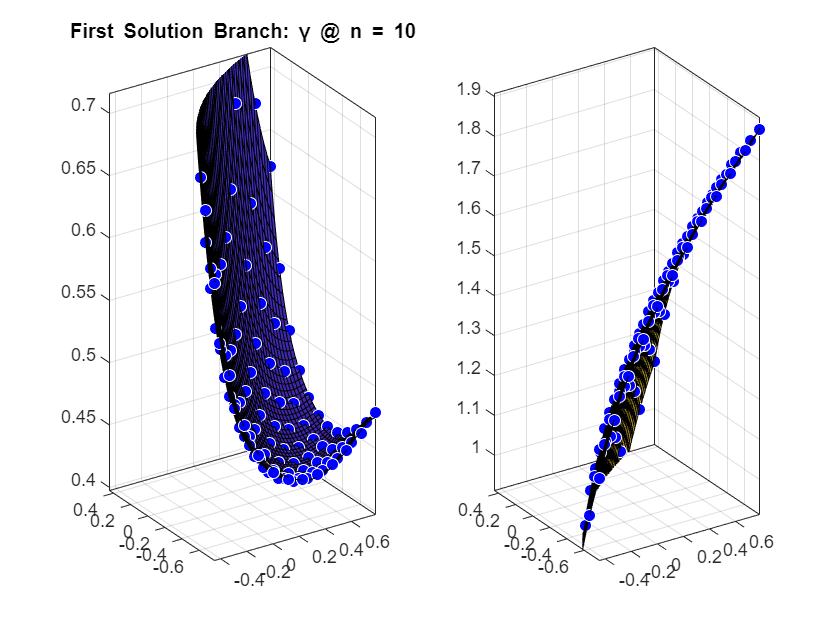

figure()
tiledlayout(1,2)

nexttile
plot(G2_fit, [B1(~isnan(G2)) B2(~isnan(G2))], G2(~isnan(G2)));
zlim([min(G2, [], 'all')-0.03 max(G2, [], 'all')+0.03]);
view([-33.300 12.000]);  
title(['First Solution Branch: \gamma @ n = ', num2str(n)]);
G3_fit = fit([B1(~isnan(G3)) B2(~isnan(G3))], G3(~isnan(G3)), 'poly55', 'Normalize', 'on');
nexttile
plot(G3_fit, [B1(~isnan(G3)) B2(~isnan(G3))], G3(~isnan(G3)));
zlim([min(G3, [], 'all')-0.03 max(G3, [], 'all')+0.03]);
view([-33.300 12.000]);

Let's do the same for the other surfaces,

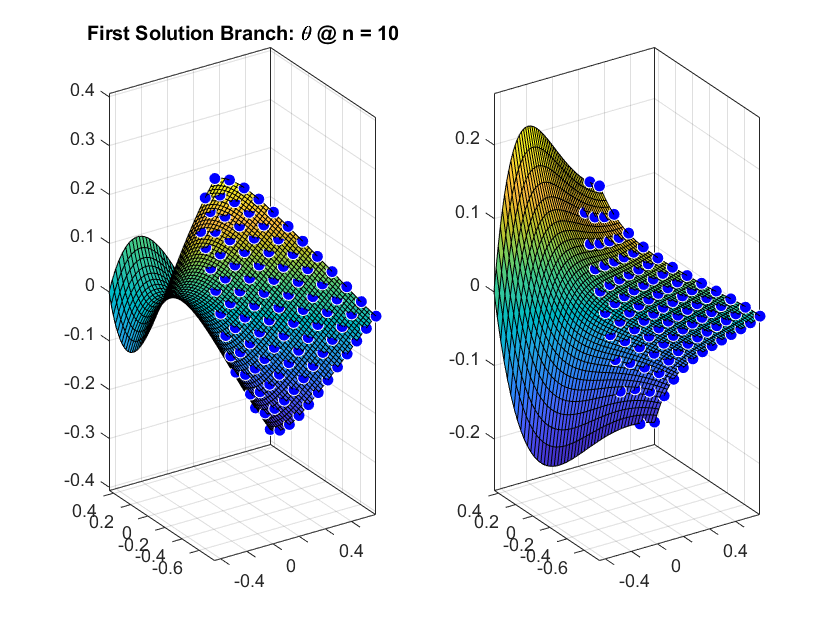

figure()
tiledlayout(1,2)

nexttile
Th2_fit = fit([B1(~isnan(Th2)) B2(~isnan(Th2))], Th2(~isnan(Th2)), 'poly55', 'Normalize', 'on');
plot(Th2_fit, [B1(~isnan(Th2)) B2(~isnan(Th2))], Th2(~isnan(Th2)));
zlim([min(Th2, [], 'all')-0.03 max(Th2, [], 'all')+0.03]);
view([-33.300 12.000]);  
title(['First Solution Branch: \theta @ n = ', num2str(n)]);
Th3_fit = fit([B1(~isnan(Th3)) B2(~isnan(Th3))], Th3(~isnan(Th3)), 'poly55', 'Normalize', 'on');
nexttile
plot(Th3_fit, [B1(~isnan(Th3)) B2(~isnan(Th3))], Th3(~isnan(Th3)));
zlim([min(Th3, [], 'all')-0.03 max(Th3, [], 'all')+0.03]);
view([-33.300 12.000]);

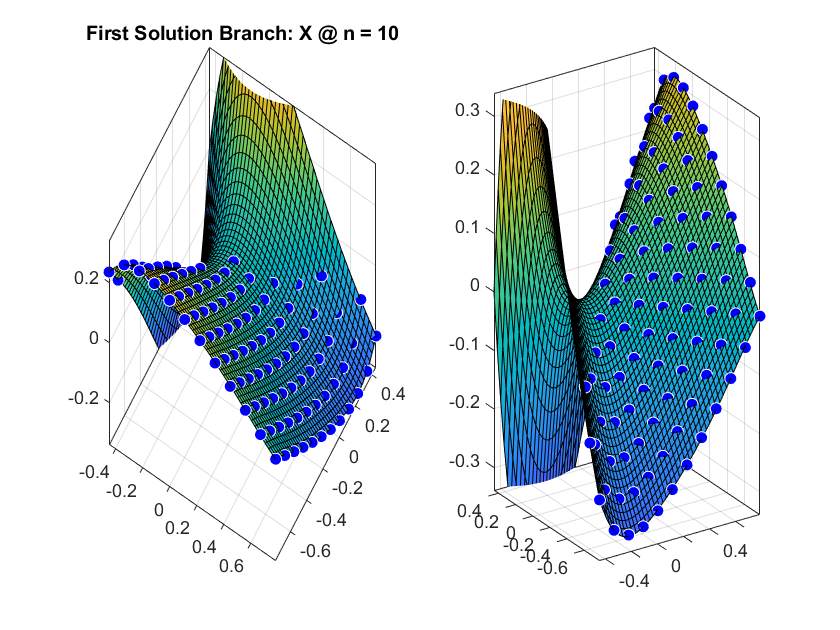

figure()
tiledlayout(1,2)

nexttile
X2_fit = fit([B1(~isnan(X2)) B2(~isnan(X2))], X2(~isnan(X2)), 'poly55', 'Normalize', 'on');
plot(X2_fit, [B1(~isnan(X2)) B2(~isnan(X2))], X2(~isnan(X2)));
zlim([min(X2, [], 'all')-0.03 max(X2, [], 'all')+0.03]);
view([31.069 48.000]); 
title(['First Solution Branch: X @ n = ', num2str(n)]);
X3_fit = fit([B1(~isnan(X3)) B2(~isnan(X3))], X3(~isnan(X3)), 'poly55', 'Normalize', 'on');
nexttile
plot(X3_fit, [B1(~isnan(X3)) B2(~isnan(X3))], X3(~isnan(X3)));
zlim([min(X3, [], 'all')-0.03 max(X3, [], 'all')+0.03]);
view([-33.300 12.000]);

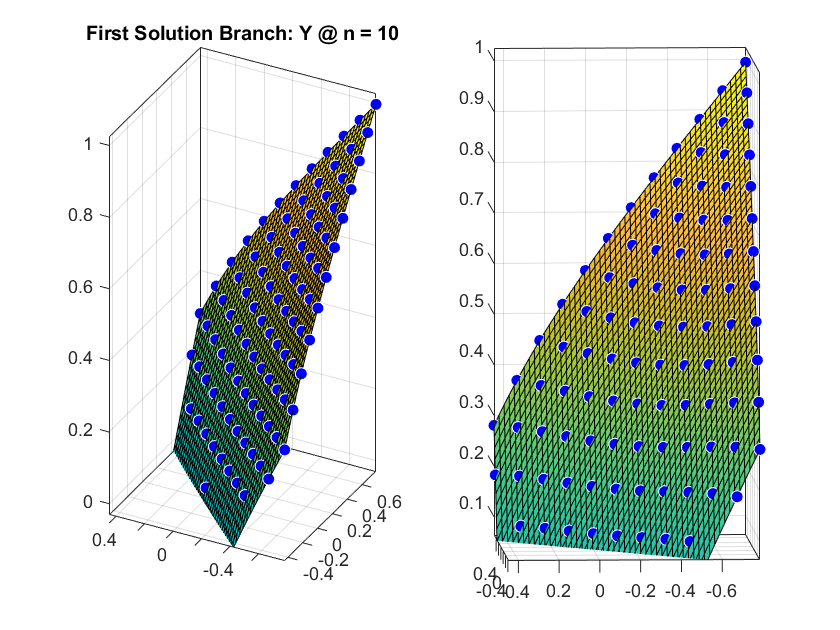

figure()
tiledlayout(1,2)

nexttile
Y2_fit = fit([B1(~isnan(Y2)) B2(~isnan(Y2))], Y2(~isnan(Y2)), 'poly55', 'Normalize', 'on');
plot(Y2_fit, [B1(~isnan(Y2)) B2(~isnan(Y2))], Y2(~isnan(Y2)));
zlim([min(Y2, [], 'all')-0.03 max(Y2, [], 'all')+0.03]);
view([-62.558 15.000]); 
title(['First Solution Branch: Y @ n = ', num2str(n)]);
Y3_fit = fit([B1(~isnan(Y3)) B2(~isnan(Y3))], Y3(~isnan(Y3)), 'poly55', 'Normalize', 'on');
nexttile
plot(Y3_fit, [B1(~isnan(Y3)) B2(~isnan(Y3))], Y3(~isnan(Y3)));
zlim([min(Y3, [], 'all')-0.03 max(Y3, [], 'all')+0.03]);
view([-93.280 3.000]);

With this, we have successfully parameterized the locomotion surfaces and the boundaries using polynomial approximations.